## 境界位置が7.9 mmにあるという情報を事前に与えた場合．

"H:/experiments/2018_11_07_IMCL_estimation_principle_verifiacation/ex2018_11_08_path_only_including_MT_focaldepth00079m_2layers.m"

%%%%%%%%%%%%%%%%%%%%%%%%%%%%％％％％％％％%%%%%
% ch 50直下のピクセルにフォーカスをかける．
% フォーカス深度を１グリッドずつ変化させて，開口合成受信データを生成する．
% F値を固定する．最近接距離をいくつに設定する？
% x-axis: 20 mmのときに全素子を使うという前提を設ける．
% 対象にする媒質データ：case26を用いる．
% IMCL割合を0 %に固定する．
% kgrid.x_vec が0となるのは251番目の要素．
% グリッド幅が0.1 mm
% 素子間ピッチが0.4 mm
% よって，最近接深度(最近接距離は0.4 mm)
% 深度ごとの細かい素子割当は，floor()を用いる．
% 整相加算の際に参照する音速を1580 m/sとする．
% 整相加算の前に参照点と受信chごとの振幅(ヒルベルト変換後絶対値)最大値との距離の
% 合計を評価関数として媒質の均質性を評価することも同時に行う．
% update:rf-dataの配列サイズが大きくなってきたので，変数区分を細分化して各変数の呼び出し速度を上げる．[2018/11/05]
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
clear;
load("H:/data/kwave/config/t_pos_2board.mat");
load("H:/data/kwave/medium/2018_11_07_layer_medium/reference.mat")
pathname = sprintf('H:/data/kwave/result/2018_11_07_layer_medium/Layer_medium_boundary_7.9mm_ IMCL%d%%',1);
cd(pathname);
load('rfdata.mat');
load('kgrid.mat');
% load("H:/data/kwave/result/2018_10_21_point_medium/point_mudium5MHz/rfdata.mat");
% load("H:/data/kwave/result/2018_10_21_point_medium/point_mudium5MHz/medium.mat");
% load("H:/data/kwave/result/2018_10_21_point_medium/point_mudium5MHz/kgrid.mat");

% 初期設定
v_fat = 1450;%[m/s]
v_muscle = 1580;%[m/s]
rate_IMCL = linspace(1,20,20);
v_reference = zeros(1,length(rate_IMCL));
t_facing_distance = 0.04;%[m]
[~,num_receiver,num_transmitter] = size(rfdata);
num_echo_receiver = num_transmitter;
num_rate_IMCL = length(rate_IMCL);
num_medium  = num_rate_IMCL;
reference_point = zeros(1,num_echo_receiver);
reference_point_lowerlimit = zeros(1,num_echo_receiver);%均質性評価のためのRFデータマスキングに使う
reference_point_upperlimit = zeros(1,num_echo_receiver);%均質性評価のためのRFデータマスキングに使う
point_maxAmp_in_mask = zeros(1,num_echo_receiver);%マスク処理後のRFデータで振幅最大のサンプル点情報
distance_from_focal_point_all = zeros(1,num_echo_receiver);
% focal_signal_total = zeros(length(rate_IMCL),num_depth);
% focal_signal_total2 = zeros(length(rate_IMCL),num_depth);
focal_amp = zeros(1,num_echo_receiver);
% focal_phase = zeros(length(rate_IMCL),num_depth,num_echo_receiver);
homogeneity_percel = zeros(num_rate_IMCL,num_echo_receiver);
homogeneity_total = zeros(num_rate_IMCL,num_medium);


num_depth = (t_pos(2,1)-t_pos(2,101))/kgrid.dx - 3;%'3'とあるのは，最近接距離が0.4 mmであることを考慮している．
focal_depth = zeros(1,num_depth);
focal_point = zeros(2,num_depth);
for ii = 1:num_depth
    focal_depth(1,ii) = (ii+3)*kgrid.dx;
    focal_point(2,ii) = t_pos(2,1)-focal_depth(1,ii);
    focal_point(1,ii) = 0;
end


for ll = 1:20
    pathname = sprintf('H:/data/kwave/result/2018_11_07_layer_medium/Layer_medium_boundary_7.9mm_ IMCL%d%%',ll);
    cd(pathname);
    load('rfdata.mat');
    load('kgrid.mat');
    [num_sample,~,~] = size(rfdata);
    focused_rfdata = zeros(num_sample,num_echo_receiver);
    focused_rfdata_masked = zeros(num_sample,num_echo_receiver);
    focused_rfdata_amp = zeros(num_sample,num_echo_receiver);
    focused_rfdata_amp_masked = zeros(num_sample,num_echo_receiver);
    for kk = 1:num_rate_IMCL
        v_reference(1,kk) = v_muscle*(1-rate_IMCL(1,kk)/100) + v_fat*(rate_IMCL(1,kk)/100);
        for ii = k
            target_element = find((-focal_depth(1,ii)/2<=t_pos(1,1:100)&(t_pos(1,1:100)<=focal_depth(1,ii)/2)));
            distance_from_focal_point = zeros(1,length(target_element));
            %受信用の参照点算出
            for jj = 1:num_echo_receiver
                distance_from_focal_point_all(1,jj) = norm(t_pos(:,jj) - focal_point(:,ii));
                delay_time_all = round(((distance_from_focal_point_all - focal_depth(1,ii))/v_reference(1,kk))/kgrid.dt);%[sample]
                reference_point(1,jj) = round(delay_time_all(1,jj)+(2*focal_depth(1,ii)/v_reference(1,kk))/kgrid.dt+24);
                %25はfocal_amplitudeを最大にするオフセット．
                reference_point_lowerlimit(1,jj) ...
                    = round(delay_time_all(1,jj)*(v_reference(1,kk)/v_muscle)+(2*focal_depth(1,ii)/v_muscle)/kgrid.dt+24-1);
                reference_point_upperlimit(1,jj) ...
                    = round(delay_time_all(1,jj)*(v_reference(1,kk)/v_fat)+(2*focal_depth(1,ii)/v_fat)/kgrid.dt+24);
                %どんなに遅延しても早く到達してもこの範囲内に焦点位置からのエコーパルスが入っているであろう上限・下限
            end
            %送信ビームフォーミング（共通）
            for jj = 1:length(target_element)
                distance_from_focal_point(1,jj) = distance_from_focal_point_all(1,target_element(jj));
                % 遅延処理
                delay_time = delay_time_all(1,target_element(jj));%[sample]
                read_range_rfdata = length(delay_time+1:num_sample);
                focused_rfdata(1:read_range_rfdata,:) = focused_rfdata(1:read_range_rfdata,:)...
                    +  rfdata(delay_time+1:num_sample,1:100,target_element(jj));%整相加算
            end
            hilb_rfdata = hilbert(focused_rfdata);
            focused_rfdata_amp = abs(hilb_rfdata);
            %         focused_rfdata_phase(:,:,ii) = atan(imag(hilb_rfdata)./real(hilb_rfdata));
            focused_rfdata_amp_masked = focused_rfdata_amp;
            focused_rfdata_masked = focused_rfdata;
            %RFデータマスキング（均質性評価のため）
            for jj = 1:num_echo_receiver
                focused_rfdata_amp_masked(1:reference_point_lowerlimit(1,jj),jj) = 0;
                focused_rfdata_amp_masked(reference_point_upperlimit(1,jj):end,jj) = 0;
                focused_rfdata_masked(1:reference_point_lowerlimit(1,jj),jj) = 0;
                focused_rfdata_masked(reference_point_upperlimit(1,jj):end,jj) = 0;
            end
            [~,point_maxAmp_in_mask] = max(focused_rfdata_amp_masked,[],1);
            for jj = 1:length(target_element)
                %受信ビームフォーミング（整相加算のため）
                %                 focal_signal_total(kk,ii) = focal_signal_total(kk,ii)+ ...
                %                     focused_rfdata_amp(reference_point(target_element(1,jj),ii,kk),target_element(1,jj),ii,kk)/length(target_element);
                %                 focal_signal_total2(kk,ii) = focal_signal_total2(kk,ii)+ ...
                %                     focused_rfdata(reference_point(target_element(1,jj),ii,kk),target_element(1,jj),ii,kk)/length(target_element);
                %                 focal_amp(kk,ii,target_element(jj)) = ...
                %                     focused_rfdata_amp(reference_point(target_element(1,jj),ii,kk),target_element(1,jj),ii,kk)/length(target_element);
                %均質性評価指標
                homogeneity_percel(kk,jj) = abs(point_maxAmp_in_mask(1,target_element(jj)) - reference_point(1,target_element(jj)));
            end
            homogeneity_total(kk,ll) = sum(homogeneity_percel(kk,:))/length(target_element);
        end
    end
end



## 参照インデックスを， 

## 1. rfデータそのものの整相加算に用いて反射強度を計算，境界位置を推定． 

## 2. rfデータに包絡線処理をしてその最大値と参照インデックスとの距離を測っている．

##  2.が特に致命的なミス．包絡線処理をすることで，データのピークの位置が変わってしまう．この ミスは，どちらもrfデータorその絶対値を用いて議論することで対策できる．

"H:/experiments/2018_11_07_IMCL_estimation_principle_verifiacation/ex2018_11_08_path_only_MT_ecxclude_envelopingProcess_2layers.m"

%%%%%%%%%%%%%%%%%%%%%%%%%%%%％％％％％％％%%%%%
% ch 50直下のピクセルにフォーカスをかける．
% フォーカス深度を１グリッドずつ変化させて，開口合成受信データを生成する．
% F値を固定する．最近接距離をいくつに設定する？
% x-axis: 20 mmのときに全素子を使うという前提を設ける．
% 対象にする媒質データ：case26を用いる．
% IMCL割合を0 %に固定する．
% kgrid.x_vec が0となるのは251番目の要素．
% グリッド幅が0.1 mm
% 素子間ピッチが0.4 mm
% よって，最近接深度(最近接距離は0.4 mm)
% 深度ごとの細かい素子割当は，floor()を用いる．
% 整相加算の際に参照する音速を1580 m/sとする．
% 整相加算の前に参照点と受信chごとの振幅(ヒルベルト変換後絶対値)最大値との距離の
% 合計を評価関数として媒質の均質性を評価することも同時に行う．
% update:rf-dataの配列サイズが大きくなってきたので，変数区分を細分化して各変数の呼び出し速度を上げる．[2018/11/05]
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
clear;
load("H:/data/kwave/config/t_pos_2board.mat");
load("H:/data/kwave/medium/2018_11_07_layer_medium/reference.mat")
pathname = sprintf('H:/data/kwave/result/2018_11_07_layer_medium/Layer_medium_boundary_7.9mm_ IMCL%d%%',1);
cd(pathname);
load('rfdata.mat');
load('kgrid.mat');
% load("H:/data/kwave/result/2018_10_21_point_medium/point_mudium5MHz/rfdata.mat");
% load("H:/data/kwave/result/2018_10_21_point_medium/point_mudium5MHz/medium.mat");
% load("H:/data/kwave/result/2018_10_21_point_medium/point_mudium5MHz/kgrid.mat");

% 初期設定
v_fat = 1450;%[m/s]
v_muscle = 1580;%[m/s]
rate_IMCL = linspace(1,20,20);
v_reference = zeros(1,length(rate_IMCL));
t_facing_distance = 0.04;%[m]
[~,num_receiver,num_transmitter] = size(rfdata);
num_echo_receiver = num_transmitter;
num_rate_IMCL = length(rate_IMCL);
num_medium  = num_rate_IMCL;
reference_point = zeros(1,num_echo_receiver);
reference_point_lowerlimit = zeros(1,num_echo_receiver);%均質性評価のためのRFデータマスキングに使う
reference_point_upperlimit = zeros(1,num_echo_receiver);%均質性評価のためのRFデータマスキングに使う
point_maxAmp_in_mask = zeros(1,num_echo_receiver);%マスク処理後のRFデータで振幅最大のサンプル点情報
distance_from_focal_point_all = zeros(1,num_echo_receiver);
% focal_signal_total = zeros(length(rate_IMCL),num_depth);
% focal_signal_total2 = zeros(length(rate_IMCL),num_depth);
focal_amp = zeros(1,num_echo_receiver);
% focal_phase = zeros(length(rate_IMCL),num_depth,num_echo_receiver);
homogeneity_percel = zeros(num_rate_IMCL,num_echo_receiver);
homogeneity_total = zeros(num_rate_IMCL,num_medium);


num_depth = (t_pos(2,1)-t_pos(2,101))/kgrid.dx - 3;%'3'とあるのは，最近接距離が0.4 mmであることを考慮している．
focal_depth = zeros(1,num_depth);
focal_point = zeros(2,num_depth);
for ii = 1:num_depth
    focal_depth(1,ii) = (ii+3)*kgrid.dx;
    focal_point(2,ii) = t_pos(2,1)-focal_depth(1,ii);
    focal_point(1,ii) = 0;
end


for ll = 1:20
    pathname = sprintf('H:/data/kwave/result/2018_11_07_layer_medium/Layer_medium_boundary_7.9mm_ IMCL%d%%',ll);
    cd(pathname);
    load('rfdata.mat');
    load('kgrid.mat');
    [num_sample,~,~] = size(rfdata);
    focused_rfdata = zeros(num_sample,num_echo_receiver);
    focused_rfdata_masked = zeros(num_sample,num_echo_receiver);
    focused_rfdata_amp = zeros(num_sample,num_echo_receiver);
    focused_rfdata_amp_masked = zeros(num_sample,num_echo_receiver);
    for kk = 1:num_rate_IMCL
        v_reference(1,kk) = v_muscle*(1-rate_IMCL(1,kk)/100) + v_fat*(rate_IMCL(1,kk)/100);
        for ii = k
            target_element = find((-focal_depth(1,ii)/2<=t_pos(1,1:100)&(t_pos(1,1:100)<=focal_depth(1,ii)/2)));
            distance_from_focal_point = zeros(1,length(target_element));
            %受信用の参照点算出
            for jj = 1:num_echo_receiver
                distance_from_focal_point_all(1,jj) = norm(t_pos(:,jj) - focal_point(:,ii));
                delay_time_all = round(((distance_from_focal_point_all - focal_depth(1,ii))/v_reference(1,kk))/kgrid.dt);%[sample]
                reference_point(1,jj) = round(delay_time_all(1,jj)+(2*focal_depth(1,ii)/v_reference(1,kk))/kgrid.dt+25-1);
                %25はfocal_amplitudeを最大にするオフセット．
                reference_point_lowerlimit(1,jj) ...
                    = round(delay_time_all(1,jj)*(v_reference(1,kk)/v_muscle)+1+(2*focal_depth(1,ii)/v_muscle)/kgrid.dt+25-1-1);
                reference_point_upperlimit(1,jj) ...
                    = round(delay_time_all(1,jj)*(v_reference(1,kk)/v_fat)+(2*focal_depth(1,ii)/v_fat)/kgrid.dt+25-1);
                %どんなに遅延しても早く到達してもこの範囲内に焦点位置からのエコーパルスが入っているであろう上限・下限
            end
            %送信ビームフォーミング（共通）
            for jj = 1:length(target_element)
                distance_from_focal_point(1,jj) = distance_from_focal_point_all(1,target_element(jj));
                % 遅延処理
                delay_time = delay_time_all(1,target_element(jj));%[sample]
                read_range_rfdata = length(delay_time+1:num_sample);
                focused_rfdata(1:read_range_rfdata,:) = focused_rfdata(1:read_range_rfdata,:)...
                    +  rfdata(delay_time+1:num_sample,1:100,target_element(jj));%整相加算
            end
            hilb_rfdata = hilbert(focused_rfdata);
            focused_rfdata_amp = abs(hilb_rfdata);
            %         focused_rfdata_phase(:,:,ii) = atan(imag(hilb_rfdata)./real(hilb_rfdata));
            focused_rfdata_amp_masked = focused_rfdata_amp;
            focused_rfdata_masked = focused_rfdata;
            %RFデータマスキング（均質性評価のため）
            for jj = 1:num_echo_receiver
                focused_rfdata_amp_masked(1:reference_point_lowerlimit(1,jj),jj) = 0;
                focused_rfdata_amp_masked(reference_point_upperlimit(1,jj):end,jj) = 0;
                focused_rfdata_masked(1:reference_point_lowerlimit(1,jj),jj) = 0;
                focused_rfdata_masked(reference_point_upperlimit(1,jj):end,jj) = 0;
            end
            [~,point_maxAmp_in_mask] = max(focused_rfdata_masked,[],1);
            for jj = 1:length(target_element)
                %受信ビームフォーミング（整相加算のため）
                %                 focal_signal_total(kk,ii) = focal_signal_total(kk,ii)+ ...
                %                     focused_rfdata_amp(reference_point(target_element(1,jj),ii,kk),target_element(1,jj),ii,kk)/length(target_element);
                %                 focal_signal_total2(kk,ii) = focal_signal_total2(kk,ii)+ ...
                %                     focused_rfdata(reference_point(target_element(1,jj),ii,kk),target_element(1,jj),ii,kk)/length(target_element);
                %                 focal_amp(kk,ii,target_element(jj)) = ...
                %                     focused_rfdata_amp(reference_point(target_element(1,jj),ii,kk),target_element(1,jj),ii,kk)/length(target_element);
                %均質性評価指標
                homogeneity_percel(kk,jj) = abs(point_maxAmp_in_mask(1,target_element(jj)) - reference_point(1,target_element(jj)));
            end
            homogeneity_total(kk,ll) = sum(homogeneity_percel(kk,:))/length(target_element);
        end
    end
end

homogeneity = 1./homogeneity_total;
figure;
pcolor(homogeneity);
colorbar;
c = colorbar;
c.Label.String = 'homogeneity';
axis equal
axis tight
xlabel('correct IMCL percentage [%]');
ylabel('predicted IMCL percentage [%]')
exportfig('H:/result/2018_11_07_IMCL_estimation_principle_verifiacation/with_rfsignal_predeiction_vs_correct_IMCL_percentage_pcolor_eng','png',[400,350]);

figure;
pcolor(homogeneity);
colorbar;
c = colorbar;
c.Label.String = '均質度評価指標';
axis equal
axis tight
xlabel('正解IMCL占有率 [%]');
ylabel('予測IMCL占有率[%]')
exportfig('H:/result/2018_11_07_IMCL_estimation_principle_verifiacation/with_rf_signal_predeiction_vs_correct_IMCL_percentage_pcolor','png',[400,350]);

2018/11/09

境界位置を反射強度から推定→波形形状評価

"H:/experiments/2018_11_07_IMCL_estimation_principle_verifiacation/ex2018_11_08_path_only_including_MT_2layers_stroke.m"

%%%%%%%%%%%%%%%%%%%%%%%%%%%%％％％％％％％%%%%%
% 境界面を検出→参照点の妥当性評価
% ch 50直下のピクセルにフォーカスをかける．
% フォーカス深度を１グリッドずつ変化させて，開口合成受信データを生成する．
% F値を固定する．最近接距離をいくつに設定する？
% x-axis: 20 mmのときに全素子を使うという前提を設ける．
% 対象にする媒質データ：case26を用いる．
% IMCL割合を0 %に固定する．
% kgrid.x_vec が0となるのは251番目の要素．
% グリッド幅が0.1 mm
% 素子間ピッチが0.4 mm
% よって，最近接深度(最近接距離は0.4 mm)
% 深度ごとの細かい素子割当は，floor()を用いる．
% 整相加算の際に参照する音速を1580 m/sとする．
% 整相加算の前に参照点と受信chごとの振幅(ヒルベルト変換後絶対値)最大値との距離の
% 合計を評価関数として媒質の均質性を評価することも同時に行う．
% update:rf-dataの配列サイズが大きくなってきたので，変数区分を細分化して各変数の呼び出し速度を上げる．[2018/11/05]
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

clear;
load("H:/data/kwave/config/t_pos_2board.mat");
load("H:/data/kwave/medium/2018_11_07_layer_medium/reference.mat")
pathname = sprintf('H:/data/kwave/result/2018_11_07_layer_medium/Layer_medium_boundary_7.9mm_ IMCL%d%%',1);
cd(pathname);
load('rfdata.mat');
load('kgrid.mat');
% load("H:/data/kwave/result/2018_10_21_point_medium/point_mudium5MHz/rfdata.mat");
% load("H:/data/kwave/result/2018_10_21_point_medium/point_mudium5MHz/medium.mat");
% load("H:/data/kwave/result/2018_10_21_point_medium/point_mudium5MHz/kgrid.mat");

% 初期設定
v_fat = 1450;%[m/s]
v_muscle = 1580;%[m/s]
rate_IMCL = linspace(1,20,20);
v_reference = zeros(1,length(rate_IMCL));
t_facing_distance = 0.04;%[m]
[~,num_receiver,num_transmitter] = size(rfdata);
num_echo_receiver = num_transmitter;
num_rate_IMCL = length(rate_IMCL);
num_medium  = num_rate_IMCL;
reference_point = zeros(1,num_echo_receiver);
reference_point_lowerlimit = zeros(1,num_echo_receiver);%均質性評価のためのRFデータマスキングに使う
reference_point_upperlimit = zeros(1,num_echo_receiver);%均質性評価のためのRFデータマスキングに使う
point_maxAmp_in_mask = zeros(1,num_echo_receiver);%マスク処理後のRFデータで振幅最大のサンプル点情報
distance_from_focal_point_all = zeros(1,num_echo_receiver);

num_depth = (t_pos(2,1)-t_pos(2,101))/kgrid.dx - 3;%'3'とあるのは，最近接距離が0.4 mmであることを考慮している．
focal_depth = zeros(1,num_depth);
focal_point = zeros(2,num_depth);
for ii = 1:num_depth
    focal_depth(1,ii) = (ii+3)*kgrid.dx;
    focal_point(2,ii) = t_pos(2,1)-focal_depth(1,ii);
    focal_point(1,ii) = 0;
end


ind_max_signal = zeros(num_rate_IMCL,num_medium);
max_signal = zeros(num_rate_IMCL,num_medium);
homogeneity_percel = zeros(num_rate_IMCL,num_echo_receiver);
homogeneity_total = zeros(num_rate_IMCL,num_medium);

for ll = 1:num_medium
    pathname = sprintf('H:/data/kwave/result/2018_11_07_layer_medium/Layer_medium_boundary_7.9mm_ IMCL%d%%',ll);
    cd(pathname);
    load('rfdata.mat');
    load('kgrid.mat');
    [num_sample,~,~] = size(rfdata);
    focal_signal_total = zeros(num_rate_IMCL,num_depth);
    
    for kk = 1:num_rate_IMCL
        %% 反射強度プロファイルを求める．
        
        v_reference(1,kk) = v_muscle*(1-rate_IMCL(1,kk)/100) + v_fat*(rate_IMCL(1,kk)/100);
        for ii = 1:num_depth
            focused_rfdata = zeros(num_sample,num_echo_receiver);
            target_element = find((-focal_depth(1,ii)/2<=t_pos(1,1:100)&(t_pos(1,1:100)<=focal_depth(1,ii)/2)));
            distance_from_focal_point = zeros(1,length(target_element));
            %受信用の参照点算出
            for jj = 1:num_echo_receiver
                distance_from_focal_point_all(1,jj) = norm(t_pos(:,jj) - focal_point(:,ii));
                delay_time_all = round(((distance_from_focal_point_all - focal_depth(1,ii))/v_reference(1,kk))/kgrid.dt);%[sample]
                reference_point(1,jj) = round(delay_time_all(1,jj)+(2*focal_depth(1,ii)/v_reference(1,kk))/kgrid.dt+25-1);
            end
            %送信ビームフォーミング（共通）
            for jj = 1:length(target_element)
                
                distance_from_focal_point(1,jj) = distance_from_focal_point_all(1,target_element(jj));
                % 遅延処理
                delay_time = delay_time_all(1,target_element(jj));%[sample]
                read_range_rfdata = length(delay_time+1:num_sample);
                focused_rfdata(1:read_range_rfdata,:) = focused_rfdata(1:read_range_rfdata,:)...
                    +  rfdata(delay_time+1:num_sample,1:100,target_element(jj));%整相加算
            end
            for jj = 1:length(target_element)
                %受信ビームフォーミング（整相加算のため）
                focal_signal_total(kk,ii) = focal_signal_total(kk,ii)+ ...
                    focused_rfdata(reference_point(1,target_element(1,jj)),target_element(1,jj))/length(target_element);
            end
        end
        %% 反射強度が最大の焦点位置を探索．
        [max_tmp,ind_tmp] = findpeaks(abs(focal_signal_total(kk,:)),'Npeaks',1,'SortStr','descend');
        ind_max_signal(kk,ll) = ind_tmp;
        max_signal(kk,ll) = max_tmp;
        ii = ind_tmp;
        %% 参照点と波面との誤差を評価．
        focused_rfdata = zeros(num_sample,num_echo_receiver);
        %         focused_rfdata_masked = zeros(num_sample,num_echo_receiver);
        target_element = find((-focal_depth(1,ii)/2<=t_pos(1,1:100)&(t_pos(1,1:100)<=focal_depth(1,ii)/2)));
        distance_from_focal_point = zeros(1,length(target_element));
        %受信用の参照点算出
        for jj = 1:num_echo_receiver
            distance_from_focal_point_all(1,jj) = norm(t_pos(:,jj) - focal_point(:,ii));
            delay_time_all = round(((distance_from_focal_point_all - focal_depth(1,ii))/v_reference(1,kk))/kgrid.dt);%[sample]
            reference_point(1,jj) = round(delay_time_all(1,jj)+(2*focal_depth(1,ii)/v_reference(1,kk))/kgrid.dt+25-1);
            %25はfocal_amplitudeを最大にするオフセット．
            reference_point_lowerlimit(1,jj) ...
                = round(delay_time_all(1,jj)*(v_reference(1,kk)/v_muscle)+(2*focal_depth(1,ii)/v_muscle)/kgrid.dt+25-1-1);
            reference_point_upperlimit(1,jj) ...
                = round(delay_time_all(1,jj)*(v_reference(1,kk)/v_fat)+(2*focal_depth(1,ii)/v_fat)/kgrid.dt+25-1);
            %どんなに遅延しても早く到達してもこの範囲内に焦点位置からのエコーパルスが入っているであろう上限・下限
        end
        %送信ビームフォーミング（共通）
        for jj = 1:length(target_element)
            distance_from_focal_point(1,jj) = distance_from_focal_point_all(1,target_element(jj));
            % 遅延処理
            delay_time = delay_time_all(1,target_element(jj));%[sample]
            read_range_rfdata = length(delay_time+1:num_sample);
            focused_rfdata(1:read_range_rfdata,:) = focused_rfdata(1:read_range_rfdata,:)...
                +  rfdata(delay_time+1:num_sample,1:100,target_element(jj));%整相加算
        end
        %         hilb_rfdata = hilbert(focused_rfdata);
        %         focused_rfdata_amp = abs(hilb_rfdata);
        %         focused_rfdata_amp_masked = focused_rfdata_amp;
        focused_rfdata_masked = focused_rfdata;
        %RFデータマスキング（均質性評価のため）
        for jj = 1:num_echo_receiver
            %             focused_rfdata_amp_masked(1:reference_point_lowerlimit(1,jj),jj) = 0;
            %             focused_rfdata_amp_masked(reference_point_upperlimit(1,jj):end,jj) = 0;
            focused_rfdata_masked(1:reference_point_lowerlimit(1,jj),jj) = 0;
            focused_rfdata_masked(reference_point_upperlimit(1,jj):end,jj) = 0;
        end
        [~,point_maxAmp_in_mask] = max(focused_rfdata_masked,[],1);
        for jj = 1:length(target_element)
            %均質性評価指標
            homogeneity_percel(kk,jj) = abs(point_maxAmp_in_mask(1,target_element(jj)) - reference_point(1,target_element(jj)));
        end
        homogeneity_total(kk,ll) = sum(homogeneity_percel(kk,:))/length(target_element);
    end
end

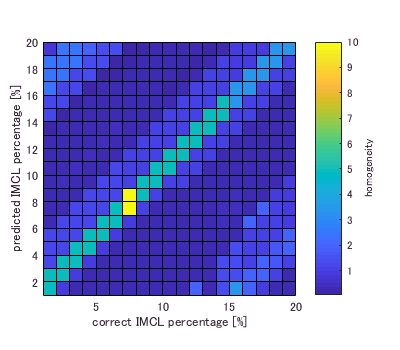

load("H:/result/2018_11_07_IMCL_estimation_principle_verifiacation/2018_11_09_with_rfsignal_homogeneity_SingleLayer_boundary_7.9mm_varied_focaldepth_20x20.mat")
homogeneity = 1./homogeneity_total;
figure;
pcolor(homogeneity);
colorbar;
c = colorbar;
c.Label.String = 'homogeneity';
axis equal
axis tight
xlabel('correct IMCL percentage [%]');
ylabel('predicted IMCL percentage [%]')
exportfig('H:/result/2018_11_07_IMCL_estimation_principle_verifiacation/2018_11_09_boundary_position_detection_with_rfsignal_predeiction_vs_correct_IMCL_percentage_pcolor_eng','png',[400,350]);

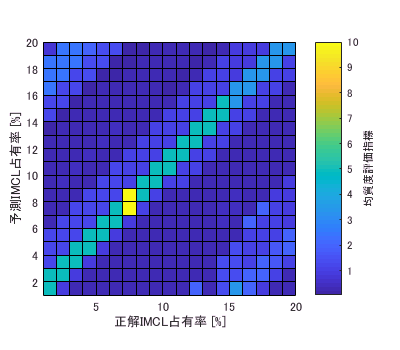

homogeneity = 1./homogeneity_total;
figure;
pcolor(homogeneity);
colorbar;
c = colorbar;
c.Label.String = '均質度評価指標';
axis equal
axis tight
xlabel('正解IMCL占有率 [%]');
ylabel('予測IMCL占有率 [%]')
exportfig('H:/result/2018_11_07_IMCL_estimation_principle_verifiacation/2018_11_09_boundary_position_detection_with_rfsignal_predeiction_vs_correct_IMCL_percentage_pcolor','png',[400,350]);

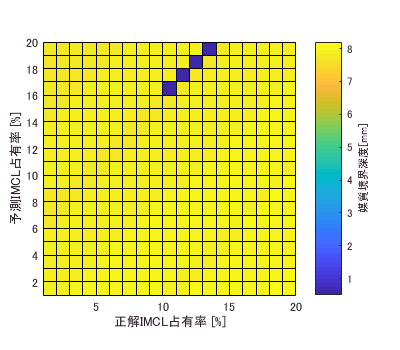

figure;
tmp = zeros(20,20);
for ii = 1:20
    tmp(ii,:) = focal_depth(1,ind_max_signal(ii,:))*1e3;
end
pcolor(tmp);
c = colorbar;
c.Label.String = '媒質境界深度[mm]';
axis equal
axis tight
xlabel('正解IMCL占有率 [%]');
ylabel('予測IMCL占有率 [%]');
axis equal
axis tight
exportfig('H:/result/2018_11_07_IMCL_estimation_principle_verifiacation/2018_11_09_detection_depth_with_errors_boundary_position_detection_with_rfsignal_predeiction_vs_correct_IMCL_percentage_pcolor','png',[400,350]);

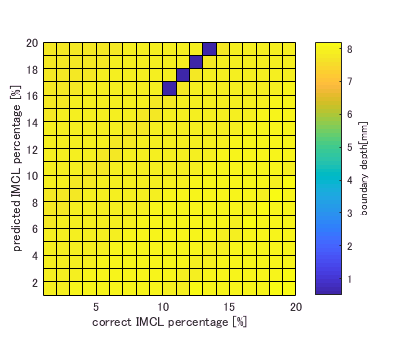

figure;
tmp = zeros(20,20);
for ii = 1:20
    tmp(ii,:) = focal_depth(1,ind_max_signal(ii,:))*1e3;
end
pcolor(tmp);
c = colorbar;
c.Label.String = 'boundary depth[mm]';
axis equal
axis tight
xlabel('correct IMCL percentage [%]');
ylabel('predicted IMCL percentage [%]');
axis equal
axis tight
exportfig('H:/result/2018_11_07_IMCL_estimation_principle_verifiacation/2018_11_09_detection_depth_with_errors_boundary_position_detection_with_rfsignal_predeiction_vs_correct_IMCL_percentage_pcolor_eng','png',[400,350]);

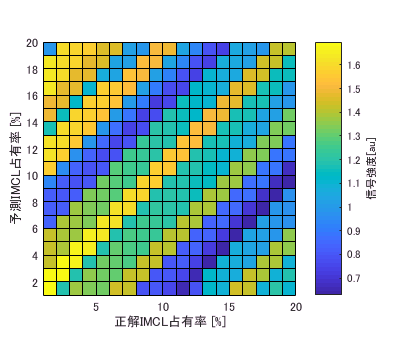

figure;
pcolor(max_signal);
c = colorbar;
c.Label.String = '信号強度[au]';
axis equal
axis tight
xlabel('正解IMCL占有率 [%]');
ylabel('予測IMCL占有率 [%]');
axis equal
axis tight
exportfig('H:/result/2018_11_07_IMCL_estimation_principle_verifiacation/2018_11_09_max_intensity_with_errors_boundary_position_detection_with_rfsignal_predeiction_vs_correct_IMCL','png',[400,350]);

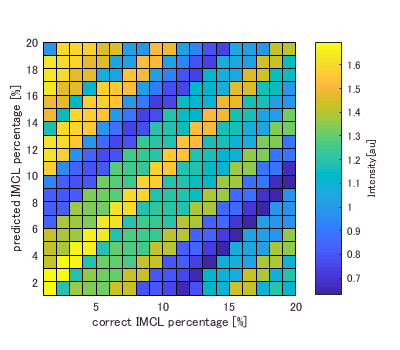

figure;
pcolor(max_signal);
c = colorbar;
c.Label.String = 'Intensity[au]';
axis equal
axis tight
xlabel('correct IMCL percentage [%]');
ylabel('predicted IMCL percentage [%]');
axis equal
axis tight
exportfig('H:/result/2018_11_07_IMCL_estimation_principle_verifiacation/2018_11_09_max_intensity_with_errors_boundary_position_detection_with_rfsignal_predeiction_vs_correct_IMCL_percentage_pcolor_eng','png',[400,350]);

## 反射強度による境界位置検出におけるエラーの調査

`正解IMCL占有率: 10 %, 予測IMCL占有率: 16 %において誤検出が見られた．このときと，検出が正しく機能した，正解IMCL占有率： 10 %, 予測IMCL占有率: 10 %での結果(focal_signal_total``[``dim={20,20}``]``)を比較して，上述したピーク関数を用いる推定方法の問題点を明らかにする．`

`"H:/experiments/2018_11_07_IMCL_estimation_principle_verifiacation/ex2018_11_08_path_only_including_MT_2layers_stroke2.m"`

%%%%%%%%%%%%%%%%%%%%%%%%%%%%％％％％％％％%%%%%
% 境界面を検出→参照点の妥当性評価
% ch 50直下のピクセルにフォーカスをかける．
% フォーカス深度を１グリッドずつ変化させて，開口合成受信データを生成する．
% F値を固定する．最近接距離をいくつに設定する？
% x-axis: 20 mmのときに全素子を使うという前提を設ける．
% 対象にする媒質データ：case26を用いる．
% IMCL割合を0 %に固定する．
% kgrid.x_vec が0となるのは251番目の要素．
% グリッド幅が0.1 mm
% 素子間ピッチが0.4 mm
% よって，最近接深度(最近接距離は0.4 mm)
% 深度ごとの細かい素子割当は，floor()を用いる．
% 整相加算の際に参照する音速を1580 m/sとする．
% 整相加算の前に参照点と受信chごとの振幅(ヒルベルト変換後絶対値)最大値との距離の
% 合計を評価関数として媒質の均質性を評価することも同時に行う．
% update:rf-dataの配列サイズが大きくなってきたので，変数区分を細分化して各変数の呼び出し速度を上げる．[2018/11/05]
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

clear;
load("H:/data/kwave/config/t_pos_2board.mat");
load("H:/data/kwave/medium/2018_11_07_layer_medium/reference.mat")
pathname = sprintf('H:/data/kwave/result/2018_11_07_layer_medium/Layer_medium_boundary_7.9mm_ IMCL%d%%',1);
cd(pathname);
load('rfdata.mat');
load('kgrid.mat');
% load("H:/data/kwave/result/2018_10_21_point_medium/point_mudium5MHz/rfdata.mat");
% load("H:/data/kwave/result/2018_10_21_point_medium/point_mudium5MHz/medium.mat");
% load("H:/data/kwave/result/2018_10_21_point_medium/point_mudium5MHz/kgrid.mat");

% 初期設定
v_fat = 1450;%[m/s]
v_muscle = 1580;%[m/s]
rate_IMCL = linspace(1,20,20);
v_reference = zeros(1,length(rate_IMCL));
t_facing_distance = 0.04;%[m]
[~,num_receiver,num_transmitter] = size(rfdata);
num_echo_receiver = num_transmitter;
num_rate_IMCL = length(rate_IMCL);
num_medium  = num_rate_IMCL;
reference_point = zeros(1,num_echo_receiver);
reference_point_lowerlimit = zeros(1,num_echo_receiver);%均質性評価のためのRFデータマスキングに使う
reference_point_upperlimit = zeros(1,num_echo_receiver);%均質性評価のためのRFデータマスキングに使う
point_max_in_mask = zeros(1,num_echo_receiver);%マスク処理後のRFデータで振幅最大のサンプル点情報
distance_from_focal_point_all = zeros(1,num_echo_receiver);

num_depth = (t_pos(2,1)-t_pos(2,101))/kgrid.dx - 3;%'3'とあるのは，最近接距離が0.4 mmであることを考慮している．
focal_depth = zeros(1,num_depth);
focal_point = zeros(2,num_depth);
for ii = 1:num_depth
    focal_depth(1,ii) = (ii+3)*kgrid.dx;
    focal_point(2,ii) = t_pos(2,1)-focal_depth(1,ii);
    focal_point(1,ii) = 0;
end


ind_max_signal = zeros(num_rate_IMCL,num_medium);
max_signal = zeros(num_rate_IMCL,num_medium);
homogeneity_percel = zeros(num_rate_IMCL,num_echo_receiver);
homogeneity_total = zeros(num_rate_IMCL,num_medium);
focal_signal_total = zeros(num_depth,num_rate_IMCL,num_medium);
for ll = 10
    pathname = sprintf('H:/data/kwave/result/2018_11_07_layer_medium/Layer_medium_boundary_7.9mm_ IMCL%d%%',ll);
    cd(pathname);
    load('rfdata.mat');
    load('kgrid.mat');
    [num_sample,~,~] = size(rfdata);

    
    for kk = 10:6:16
        %% 反射強度プロファイルを求める．
        v_reference(1,kk) = v_muscle*(1-rate_IMCL(1,kk)/100) + v_fat*(rate_IMCL(1,kk)/100);
        for ii = 1:num_depth
            focused_rfdata = zeros(num_sample,num_echo_receiver);
            target_element = find((-focal_depth(1,ii)/2<=t_pos(1,1:100)&(t_pos(1,1:100)<=focal_depth(1,ii)/2)));
            distance_from_focal_point = zeros(1,length(target_element));
            %受信用の参照点算出
            for jj = 1:num_echo_receiver
                distance_from_focal_point_all(1,jj) = norm(t_pos(:,jj) - focal_point(:,ii));
                delay_time_all = round(((distance_from_focal_point_all - focal_depth(1,ii))/v_reference(1,kk))/kgrid.dt);%[sample]
                reference_point(1,jj) = round(delay_time_all(1,jj)+(2*focal_depth(1,ii)/v_reference(1,kk))/kgrid.dt+25-1);
            end
            %送信ビームフォーミング（共通）
            for jj = 1:length(target_element)
                
                distance_from_focal_point(1,jj) = distance_from_focal_point_all(1,target_element(jj));
                % 遅延処理
                delay_time = delay_time_all(1,target_element(jj));%[sample]
                read_range_rfdata = length(delay_time+1:num_sample);
                focused_rfdata(1:read_range_rfdata,:) = focused_rfdata(1:read_range_rfdata,:)...
                    +  rfdata(delay_time+1:num_sample,1:100,target_element(jj));%整相加算
            end
            for jj = 1:length(target_element)
                %受信ビームフォーミング（整相加算のため）
                focal_signal_total(ii,kk,ll) = focal_signal_total(ii,kk,ll)+ ...
                    focused_rfdata(reference_point(1,target_element(1,jj)),target_element(1,jj))/length(target_element);
            end
        end
        %% 反射強度が最大の焦点位置を探索．
        [max_tmp,ind_tmp] = findpeaks(abs(focal_signal_total(:,kk,ll)),'Npeaks',1,'SortStr','descend');
        ind_max_signal(kk,ll) = ind_tmp;
        max_signal(kk,ll) = max_tmp;
        ii = ind_tmp;
        %% 参照点と波面との誤差を評価．
        focused_rfdata = zeros(num_sample,num_echo_receiver);
%         focused_rfdata_masked = zeros(num_sample,num_echo_receiver);
        target_element = find((-focal_depth(1,ii)/2<=t_pos(1,1:100)&(t_pos(1,1:100)<=focal_depth(1,ii)/2)));
        distance_from_focal_point = zeros(1,length(target_element));
        %受信用の参照点算出
        for jj = 1:num_echo_receiver
            distance_from_focal_point_all(1,jj) = norm(t_pos(:,jj) - focal_point(:,ii));
            delay_time_all = round(((distance_from_focal_point_all - focal_depth(1,ii))/v_reference(1,kk))/kgrid.dt);%[sample]
            reference_point(1,jj) = round(delay_time_all(1,jj)+(2*focal_depth(1,ii)/v_reference(1,kk))/kgrid.dt+25-1);
            %25はfocal_amplitudeを最大にするオフセット．
            reference_point_lowerlimit(1,jj) ...
                = round(delay_time_all(1,jj)*(v_reference(1,kk)/v_muscle)+(2*focal_depth(1,ii)/v_muscle)/kgrid.dt+25-1-1);
            reference_point_upperlimit(1,jj) ...
                = round(delay_time_all(1,jj)*(v_reference(1,kk)/v_fat)+(2*focal_depth(1,ii)/v_fat)/kgrid.dt+25-1);
            %どんなに遅延しても早く到達してもこの範囲内に焦点位置からのエコーパルスが入っているであろう上限・下限
        end
        %送信ビームフォーミング（共通）
        for jj = 1:length(target_element)
            distance_from_focal_point(1,jj) = distance_from_focal_point_all(1,target_element(jj));
            % 遅延処理
            delay_time = delay_time_all(1,target_element(jj));%[sample]
            read_range_rfdata = length(delay_time+1:num_sample);
            focused_rfdata(1:read_range_rfdata,:) = focused_rfdata(1:read_range_rfdata,:)...
                +  rfdata(delay_time+1:num_sample,1:100,target_element(jj));%整相加算
        end
        focused_rfdata_masked = focused_rfdata;
        %RFデータマスキング（均質性評価のため）
        for jj = 1:num_echo_receiver
%             focused_rfdata_amp_masked(1:reference_point_lowerlimit(1,jj),jj) = 0;
%             focused_rfdata_amp_masked(reference_point_upperlimit(1,jj):end,jj) = 0;
            focused_rfdata_masked(1:reference_point_lowerlimit(1,jj),jj) = 0;
            focused_rfdata_masked(reference_point_upperlimit(1,jj):end,jj) = 0;
        end
        [~,point_max_in_mask] = max(focused_rfdata_masked,[],1);
        for jj = 1:length(target_element)
            %均質性評価指標
            homogeneity_percel(kk,jj) = abs(point_max_in_mask(1,target_element(jj)) - reference_point(1,target_element(jj)));
        end
        homogeneity_total(kk,ll) = sum(homogeneity_percel(kk,:))/length(target_element);
    end
end

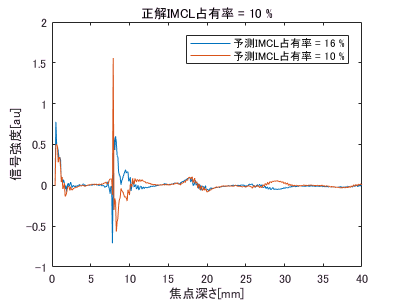

load("H:/result/2018_11_07_IMCL_estimation_principle_verifiacation/2018_11_09_with_rfsignal_homogeneity_SingleLayer_boundary_7.9mm_varied_focaldepth_error_check.mat")
figure;
plot(focal_depth*1e3,focal_signal_total(:,16,10));
hold on
plot(focal_depth*1e3,focal_signal_total(:,10,10));
title('正解IMCL占有率 = 10 %')
xlabel('焦点深さ[mm]')
ylabel('信号強度[au]')
legend('予測IMCL占有率 = 16 %','予測IMCL占有率 = 10 %')
exportfig("H:/result/2018_11_07_IMCL_estimation_principle_verifiacation/2018_11_09_focased_signal_comparison_TorF",'png',[400,300]);

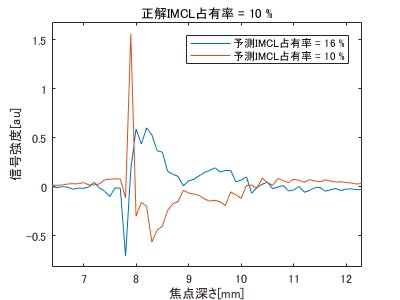

load("H:/result/2018_11_07_IMCL_estimation_principle_verifiacation/2018_11_09_with_rfsignal_homogeneity_SingleLayer_boundary_7.9mm_varied_focaldepth_error_check.mat")
figure;
plot(focal_depth*1e3,focal_signal_total(:,16,10));
hold on
plot(focal_depth*1e3,focal_signal_total(:,10,10));
title('正解IMCL占有率 = 10 %')
xlabel('焦点深さ[mm]')
ylabel('信号強度[au]')
legend('予測IMCL占有率 = 16 %','予測IMCL占有率 = 10 %')
xlim([6.4 12.3])
ylim([-0.82 1.68])
exportfig("H:/result/2018_11_07_IMCL_estimation_principle_verifiacation/2018_11_09_focased_signal_comparison_TorF_detail",'png',[400,300]);

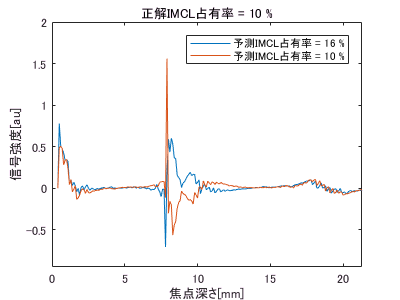

load("H:/result/2018_11_07_IMCL_estimation_principle_verifiacation/2018_11_09_with_rfsignal_homogeneity_SingleLayer_boundary_7.9mm_varied_focaldepth_error_check.mat")
figure;
plot(focal_depth*1e3,focal_signal_total(:,16,10));
hold on
plot(focal_depth*1e3,focal_signal_total(:,10,10));
title('正解IMCL占有率 = 10 %')
xlabel('焦点深さ[mm]')
ylabel('信号強度[au]')
legend('予測IMCL占有率 = 16 %','予測IMCL占有率 = 10 %')
xlim([0.0 21.3])
ylim([-0.95 2.00])
exportfig("H:/result/2018_11_07_IMCL_estimation_principle_verifiacation/2018_11_09_focased_signal_comparison_TorF_detail2",'png',[400,300]);

問題点：信号強度の絶対値が最大の箇所を探索していることにより，位相情報の考慮をしていない

対策：絶対値を取らないようにする

問題点：媒質境界位置が0.4 mm~0.5 mmと顕著に外れた位置に検出された．

対策：焦点深度0.4 mm程度の信号強度は参照しないようにする．

"H:/experiments/2018_11_07_IMCL_estimation_principle_verifiacation/ex2018_11_08_path_only_including_MT_2layers_stroke3.m"

%%%%%%%%%%%%%%%%%%%%%%%%%%%%％％％％％％％%%%%%
% 境界面を検出→参照点の妥当性評価
% ch 50直下のピクセルにフォーカスをかける．
% フォーカス深度を１グリッドずつ変化させて，開口合成受信データを生成する．
% F値を固定する．最近接距離をいくつに設定する？
% x-axis: 20 mmのときに全素子を使うという前提を設ける．
% 対象にする媒質データ：case26を用いる．
% IMCL割合を0 %に固定する．
% kgrid.x_vec が0となるのは251番目の要素．
% グリッド幅が0.1 mm
% 素子間ピッチが0.4 mm
% よって，最近接深度(最近接距離は0.4 mm)
% 深度ごとの細かい素子割当は，floor()を用いる．
% 整相加算の際に参照する音速を1580 m/sとする．
% 整相加算の前に参照点と受信chごとの振幅(ヒルベルト変換後絶対値)最大値との距離の
% 合計を評価関数として媒質の均質性を評価することも同時に行う．
% update:rf-dataの配列サイズが大きくなってきたので，変数区分を細分化して各変数の呼び出し速度を上げる．[2018/11/05]
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

clear;
load("H:/data/kwave/config/t_pos_2board.mat");
load("H:/data/kwave/medium/2018_11_07_layer_medium/reference.mat")
pathname = sprintf('H:/data/kwave/result/2018_11_07_layer_medium/Layer_medium_boundary_7.9mm_ IMCL%d%%',1);
cd(pathname);
load('rfdata.mat');
load('kgrid.mat');
% load("H:/data/kwave/result/2018_10_21_point_medium/point_mudium5MHz/rfdata.mat");
% load("H:/data/kwave/result/2018_10_21_point_medium/point_mudium5MHz/medium.mat");
% load("H:/data/kwave/result/2018_10_21_point_medium/point_mudium5MHz/kgrid.mat");

% 初期設定
v_fat = 1450;%[m/s]
v_muscle = 1580;%[m/s]
rate_IMCL = linspace(1,20,20);
v_reference = zeros(1,length(rate_IMCL));
t_facing_distance = 0.04;%[m]
[~,num_receiver,num_transmitter] = size(rfdata);
num_echo_receiver = num_transmitter;
num_rate_IMCL = length(rate_IMCL);
num_medium  = num_rate_IMCL;
reference_point = zeros(1,num_echo_receiver);
reference_point_lowerlimit = zeros(1,num_echo_receiver);%均質性評価のためのRFデータマスキングに使う
reference_point_upperlimit = zeros(1,num_echo_receiver);%均質性評価のためのRFデータマスキングに使う
point_max_in_mask = zeros(1,num_echo_receiver);%マスク処理後のRFデータで振幅最大のサンプル点情報
distance_from_focal_point_all = zeros(1,num_echo_receiver);

num_depth = (t_pos(2,1)-t_pos(2,101))/kgrid.dx - 3;%'3'とあるのは，最近接距離が0.4 mmであることを考慮している．
focal_depth = zeros(1,num_depth);
focal_point = zeros(2,num_depth);
for ii = 1:num_depth
    focal_depth(1,ii) = (ii+3)*kgrid.dx;
    focal_point(2,ii) = t_pos(2,1)-focal_depth(1,ii);
    focal_point(1,ii) = 0;
end


ind_max_signal = zeros(num_rate_IMCL,num_medium);
max_signal = zeros(num_rate_IMCL,num_medium);
homogeneity_percel = zeros(num_rate_IMCL,num_echo_receiver);
homogeneity_total = zeros(num_rate_IMCL,num_medium);
focal_signal_total = zeros(num_depth,num_rate_IMCL,num_medium);
for ll = 1:num_medium
    pathname = sprintf('H:/data/kwave/result/2018_11_07_layer_medium/Layer_medium_boundary_7.9mm_ IMCL%d%%',ll);
    cd(pathname);
    load('rfdata.mat');
    load('kgrid.mat');
    [num_sample,~,~] = size(rfdata);
    for kk = 1:num_rate_IMCL
        %% 反射強度プロファイルを求める．
        v_reference(1,kk) = v_muscle*(1-rate_IMCL(1,kk)/100) + v_fat*(rate_IMCL(1,kk)/100);
        for ii = 1:num_depth
            focused_rfdata = zeros(num_sample,num_echo_receiver);
            target_element = find((-focal_depth(1,ii)/2<=t_pos(1,1:100)&(t_pos(1,1:100)<=focal_depth(1,ii)/2)));
            distance_from_focal_point = zeros(1,length(target_element));
            %受信用の参照点算出
            for jj = 1:num_echo_receiver
                distance_from_focal_point_all(1,jj) = norm(t_pos(:,jj) - focal_point(:,ii));
                delay_time_all = round(((distance_from_focal_point_all - focal_depth(1,ii))/v_reference(1,kk))/kgrid.dt);%[sample]
                reference_point(1,jj) = round(delay_time_all(1,jj)+(2*focal_depth(1,ii)/v_reference(1,kk))/kgrid.dt+25-1);
            end
            %送信ビームフォーミング（共通）
            for jj = 1:length(target_element)
                distance_from_focal_point(1,jj) = distance_from_focal_point_all(1,target_element(jj));
                % 遅延処理
                delay_time = delay_time_all(1,target_element(jj));%[sample]
                read_range_rfdata = length(delay_time+1:num_sample);
                focused_rfdata(1:read_range_rfdata,:) = focused_rfdata(1:read_range_rfdata,:)...
                    +  rfdata(delay_time+1:num_sample,1:100,target_element(jj));%整相加算
            end
            for jj = 1:length(target_element)
                %受信ビームフォーミング（整相加算のため）
                focal_signal_total(ii,kk,ll) = focal_signal_total(ii,kk,ll)+ ...
                    focused_rfdata(reference_point(1,target_element(1,jj)),target_element(1,jj))/length(target_element);
            end
        end
        %% 反射強度が最大の焦点位置を探索．
        [max_tmp,ind_tmp] = findpeaks(focal_signal_total(:,kk,ll),'Npeaks',1,'SortStr','descend');
        ind_max_signal(kk,ll) = ind_tmp;
        max_signal(kk,ll) = max_tmp;
        ii = ind_tmp;
        %% 参照点と波面との誤差を評価．
        focused_rfdata = zeros(num_sample,num_echo_receiver);
        target_element = find((-focal_depth(1,ii)/2<=t_pos(1,1:100)&(t_pos(1,1:100)<=focal_depth(1,ii)/2)));
        distance_from_focal_point = zeros(1,length(target_element));
        %受信用の参照点算出
        for jj = 1:num_echo_receiver
            distance_from_focal_point_all(1,jj) = norm(t_pos(:,jj) - focal_point(:,ii));
            delay_time_all = round(((distance_from_focal_point_all - focal_depth(1,ii))/v_reference(1,kk))/kgrid.dt);%[sample]
            reference_point(1,jj) = round(delay_time_all(1,jj)+(2*focal_depth(1,ii)/v_reference(1,kk))/kgrid.dt+25-1);
            %25はfocal_amplitudeを最大にするオフセット．
            reference_point_lowerlimit(1,jj) ...
                = round(delay_time_all(1,jj)*(v_reference(1,kk)/v_muscle)+(2*focal_depth(1,ii)/v_muscle)/kgrid.dt+25-1-1);
            reference_point_upperlimit(1,jj) ...
                = round(delay_time_all(1,jj)*(v_reference(1,kk)/v_fat)+(2*focal_depth(1,ii)/v_fat)/kgrid.dt+25-1);
            %どんなに遅延しても早く到達してもこの範囲内に焦点位置からのエコーパルスが入っているであろう上限・下限
        end
        %送信ビームフォーミング（共通）
        for jj = 1:length(target_element)
            distance_from_focal_point(1,jj) = distance_from_focal_point_all(1,target_element(jj));
            % 遅延処理
            delay_time = delay_time_all(1,target_element(jj));%[sample]
            read_range_rfdata = length(delay_time+1:num_sample);
            focused_rfdata(1:read_range_rfdata,:) = focused_rfdata(1:read_range_rfdata,:)...
                +  rfdata(delay_time+1:num_sample,1:100,target_element(jj));%整相加算
        end
        focused_rfdata_masked = focused_rfdata;
        %RFデータマスキング（均質性評価のため）
        for jj = 1:num_echo_receiver
            focused_rfdata_masked(1:reference_point_lowerlimit(1,jj),jj) = 0;
            focused_rfdata_masked(reference_point_upperlimit(1,jj):end,jj) = 0;
        end
        [~,point_max_in_mask] = max(focused_rfdata_masked,[],1);
        for jj = 1:length(target_element)
            %均質性評価指標
            homogeneity_percel(kk,jj) = abs(point_max_in_mask(1,target_element(jj)) - reference_point(1,target_element(jj)));
        end
        homogeneity_total(kk,ll) = sum(homogeneity_percel(kk,:))/length(target_element);
    end
end
cd 'H:/result/2018_11_07_IMCL_estimation_principle_verifiacation'
save('2018_11_10_with_rfsignal_homogeneity_SingleLayer_boundary_7.9mm_varied_focaldepth_20x20_ver2.mat','ind_tmp','ind_max_signal','focal_depth','homogeneity_total','homogeneity_percel',...
    'reference_point','focused_rfdata','focused_rfdata_masked','focal_signal_total','max_signal');

load("H:/result/2018_11_07_IMCL_estimation_principle_verifiacation/2018_11_10_with_rfsignal_homogeneity_SingleLayer_boundary_7.9mm_varied_focaldepth_20x20_ver2.mat")
openfig('H:/result/2018_11_07_IMCL_estimation_principle_verifiacation/2018_11_10_max_intensity_with_errors_boundary_position_detection_with_rfsignal_predeiction_vs_correct_IMCL_percentage_pcolor_without_abs.fig')

ans =   Figure (LiveEditorCachedFigure) のプロパティ:

      Number: 33
        Name: 'Figure'
       Color: [0.9400 0.9400 0.9400]
    Position: [-944 291 400 350]
       Units: 'pixels'

  すべてのプロパティ を表示


c = colorbar;
c.Label.String = '信号強度[au]';
axis equal
axis tight
xlabel('正解IMCL占有率 [%]');
ylabel('予測IMCL占有率 [%]');
axis equal
axis tight
exportfig('H:/result/2018_11_07_IMCL_estimation_principle_verifiacation/2018_11_10_max_intensity_with_errors_boundary_position_detection_with_rfsignal_predeiction_vs_correct_IMCL_percentage_pcolor_without_abs','png',[400,350]);

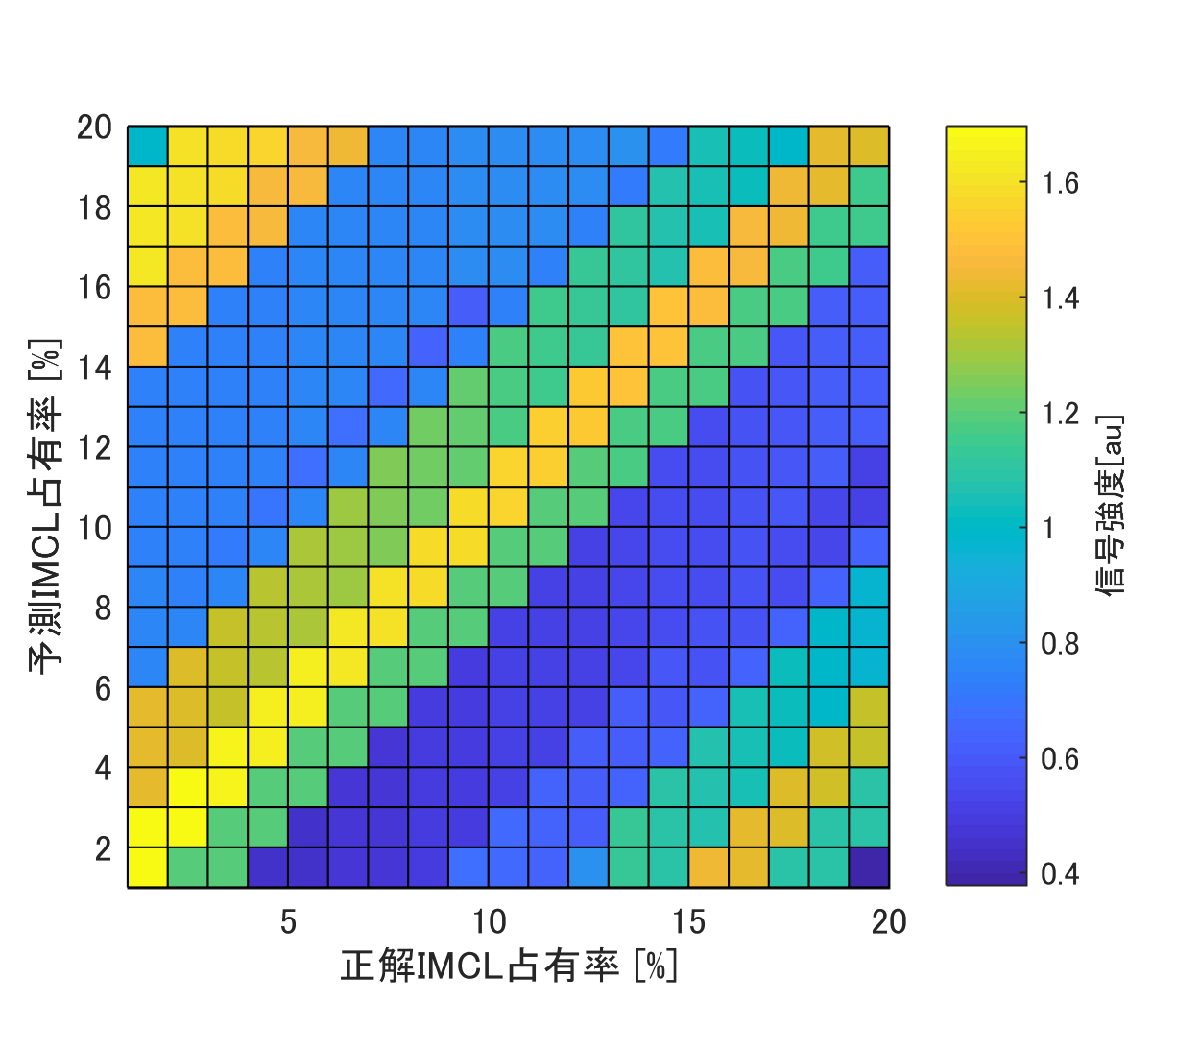

openfig('H:/result/2018_11_07_IMCL_estimation_principle_verifiacation/2018_11_10_max_intensity_with_errors_boundary_position_detection_with_rfsignal_predeiction_vs_correct_IMCL_percentage_pcolor_without_abs.fig')

ans =   Figure (LiveEditorCachedFigure) のプロパティ:

      Number: 26
        Name: 'Figure'
       Color: [0.9400 0.9400 0.9400]
    Position: [-944 291 400 350]
       Units: 'pixels'

  すべてのプロパティ を表示


c = colorbar;
c.Label.String = 'Intensity[au]';
axis equal
axis tight
xlabel('correct IMCL percentage [%]');
ylabel('predicted IMCL percentage [%]');
axis equal
axis tight
exportfig('H:/result/2018_11_07_IMCL_estimation_principle_verifiacation/2018_11_10_max_intensity_with_errors_boundary_position_detection_with_rfsignal_predeiction_vs_correct_IMCL_percentage_pcolor_without_abs_eng','png',[400,350]);

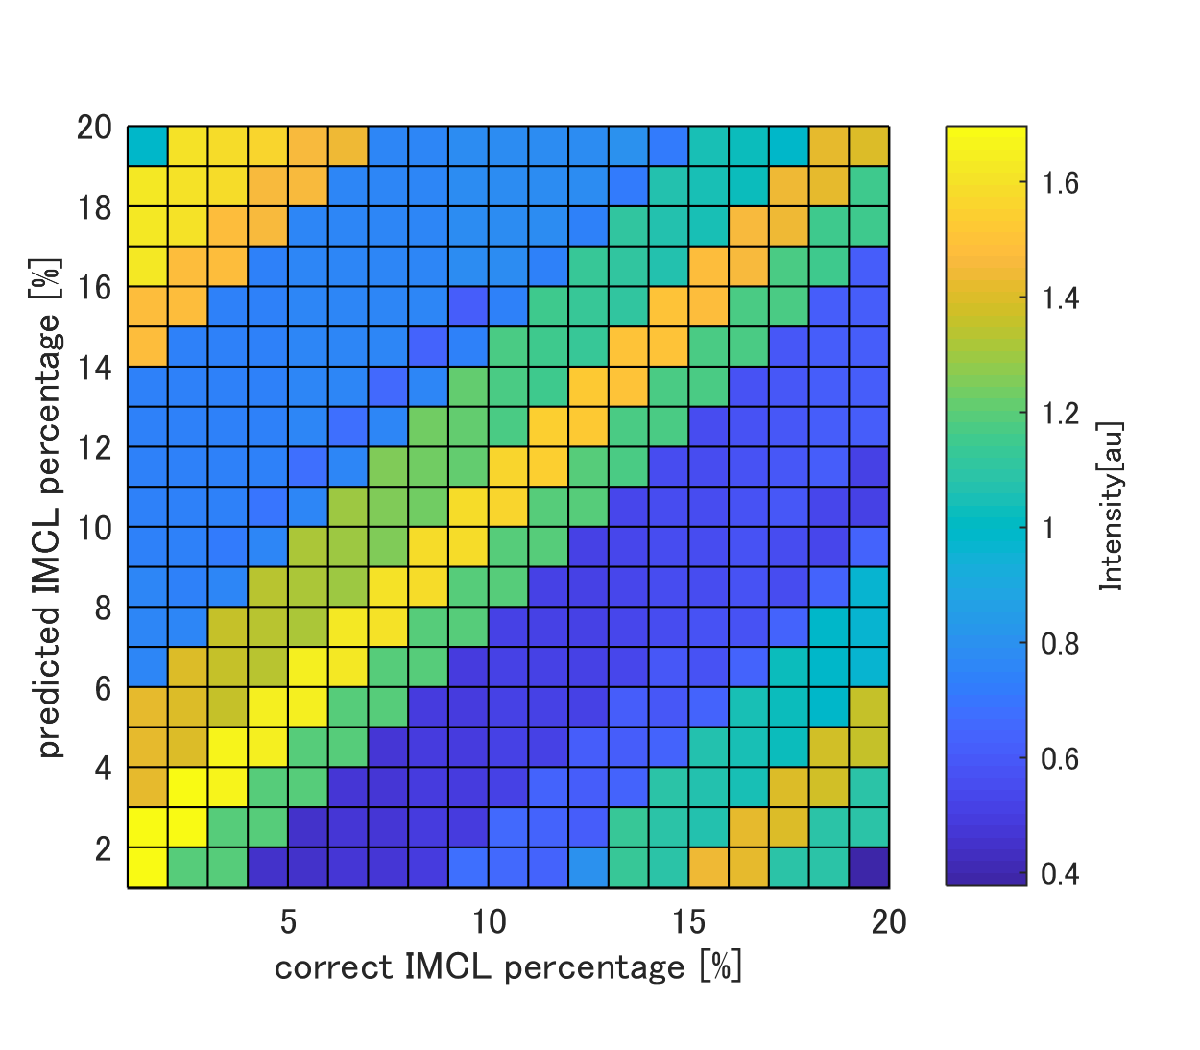

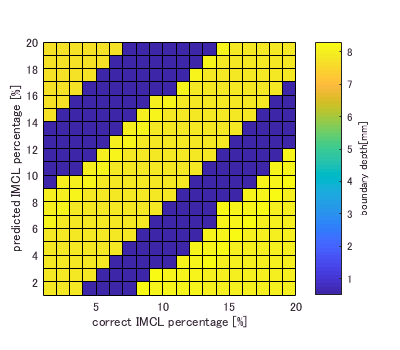

load("H:/result/2018_11_07_IMCL_estimation_principle_verifiacation/2018_11_10_with_rfsignal_homogeneity_SingleLayer_boundary_7.9mm_varied_focaldepth_20x20_ver2.mat")
figure;
tmp = zeros(20,20);
for ii = 1:20
    tmp(ii,:) = focal_depth(1,ind_max_signal(ii,:))*1e3;
end
pcolor(tmp);
c = colorbar;
c.Label.String = 'boundary depth[mm]';
axis equal
axis tight
xlabel('correct IMCL percentage [%]');
ylabel('predicted IMCL percentage [%]');
axis equal
axis tight
exportfig('H:/result/2018_11_07_IMCL_estimation_principle_verifiacation/2018_11_10_detection_depth_with_errors_boundary_position_detection_with_rfsignal_predeiction_vs_correct_IMCL_percentage_pcolor_without_abs_eng','png',[400,350]);

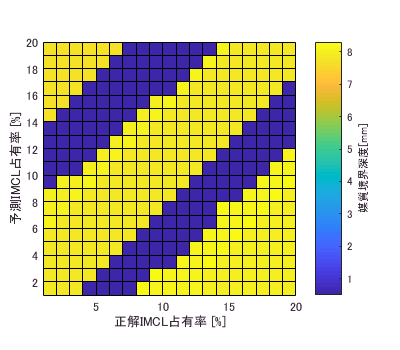

load("H:/result/2018_11_07_IMCL_estimation_principle_verifiacation/2018_11_10_with_rfsignal_homogeneity_SingleLayer_boundary_7.9mm_varied_focaldepth_20x20_ver2.mat")
figure;
tmp = zeros(20,20);
for ii = 1:20
    tmp(ii,:) = focal_depth(1,ind_max_signal(ii,:))*1e3;
end
pcolor(tmp);
c = colorbar;
c.Label.String = '媒質境界深度[mm]';
axis equal
axis tight
xlabel('正解IMCL占有率 [%]');
ylabel('予測IMCL占有率 [%]');
axis equal
axis tight
exportfig('H:/result/2018_11_07_IMCL_estimation_principle_verifiacation/2018_11_10_detection_depth_with_errors_boundary_position_detection_with_rfsignal_predeiction_vs_correct_IMCL_percentage_pcolor_without_abs','png',[400,350]);

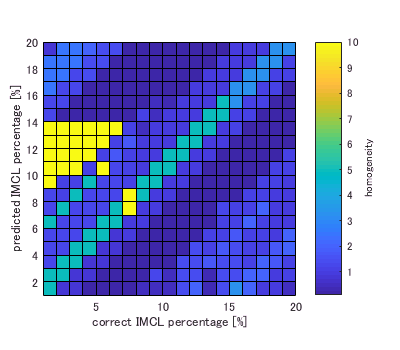

load("H:/result/2018_11_07_IMCL_estimation_principle_verifiacation/2018_11_10_with_rfsignal_homogeneity_SingleLayer_boundary_7.9mm_varied_focaldepth_20x20_ver2.mat")
homogeneity = 1./homogeneity_total;
figure;
pcolor(homogeneity);
colorbar;
c = colorbar;
c.Label.String = 'homogeneity';
axis equal
axis tight
xlabel('correct IMCL percentage [%]');
ylabel('predicted IMCL percentage [%]')
exportfig('H:/result/2018_11_07_IMCL_estimation_principle_verifiacation/2018_11_10_boundary_position_detection_with_errors_boundary_position_detection_with_rfsignal_predeiction_vs_correct_IMCL_percentage_pcolor_without_abs_eng','png',[400,350]);

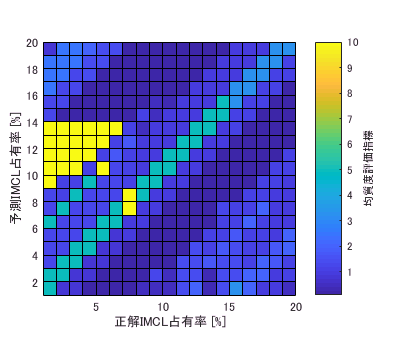

load("H:/result/2018_11_07_IMCL_estimation_principle_verifiacation/2018_11_10_with_rfsignal_homogeneity_SingleLayer_boundary_7.9mm_varied_focaldepth_20x20_ver2.mat")
homogeneity = 1./homogeneity_total;
figure;
pcolor(homogeneity);
c = colorbar;
c.Label.String = '均質度評価指標';
axis equal
axis tight
xlabel('正解IMCL占有率 [%]');
ylabel('予測IMCL占有率 [%]')
exportfig('H:/result/2018_11_07_IMCL_estimation_principle_verifiacation/2018_11_10_boundary_position_detection_with_errors_boundary_position_detection_with_rfsignal_predeiction_vs_correct_IMCL_percentage_pcolor_without_abs_e','png',[400,350]);

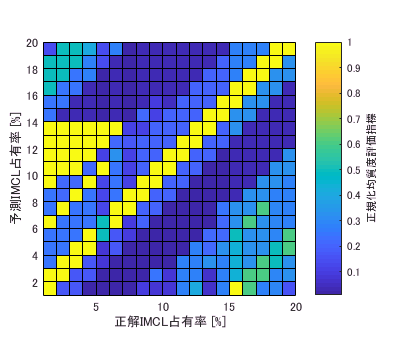

load("H:\result\2018_11_07_IMCL_estimation_principle_verifiacation\2018_11_11_maxrfsignal_detect_boundary_2layers\result.mat")
figure;
pcolor(homogeneity_total_normalized);
c = colorbar;
c.Label.String = '正規化均質度評価指標';
axis equal
axis tight
xlabel('正解IMCL占有率 [%]');
ylabel('予測IMCL占有率 [%]');
exportfig('H:/result/2018_11_07_IMCL_estimation_principle_verifiacation/2018_11_13_homogeneity_normalized','png',[400,350]);

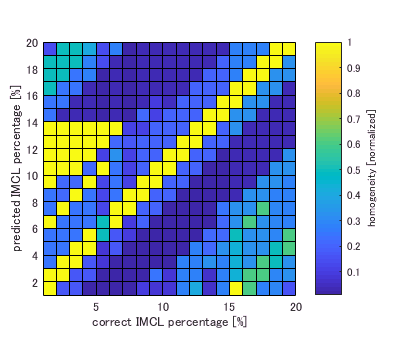

load("H:\result\2018_11_07_IMCL_estimation_principle_verifiacation\2018_11_11_maxrfsignal_detect_boundary_2layers\result.mat")
figure;
pcolor(homogeneity_total_normalized);
colorbar;
c = colorbar;
c.Label.String = 'homogeneity [normalized]';
axis equal
axis tight
xlabel('correct IMCL percentage [%]');
ylabel('predicted IMCL percentage [%]')
exportfig('H:/result/2018_11_07_IMCL_estimation_principle_verifiacation/2018_11_13_homogeneity_normalized_eng','png',[400,350]);

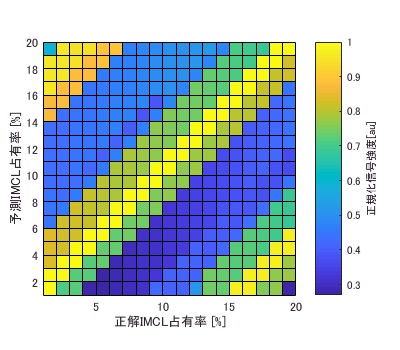

load("H:\result\2018_11_07_IMCL_estimation_principle_verifiacation\2018_11_11_maxrfsignal_detect_boundary_2layers\result.mat")
figure;
pcolor(max_signal_normalized);
c = colorbar;
c.Label.String = '正規化信号強度[au]';
axis equal
axis tight
xlabel('正解IMCL占有率 [%]');
ylabel('予測IMCL占有率 [%]');
axis equal
axis tight
exportfig('H:/result/2018_11_07_IMCL_estimation_principle_verifiacation/2018_11_13_intensity_normalized','png',[400,350]);

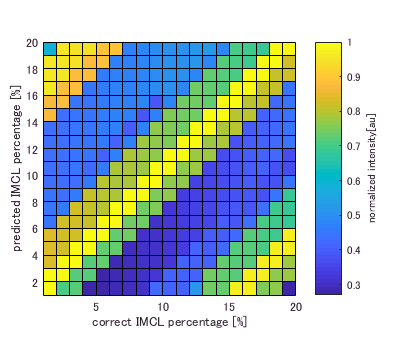

load("H:\result\2018_11_07_IMCL_estimation_principle_verifiacation\2018_11_11_maxrfsignal_detect_boundary_2layers\result.mat")
figure;
pcolor(max_signal_normalized);
c = colorbar;
c.Label.String = 'normalized intensity[au]';
axis equal
axis tight
xlabel('correct IMCL percentage [%]');
ylabel('predicted IMCL percentage [%]');
axis equal
axis tight
exportfig('H:/result/2018_11_07_IMCL_estimation_principle_verifiacation/2018_11_13_intensity_normalized_eng','png',[400,350]);

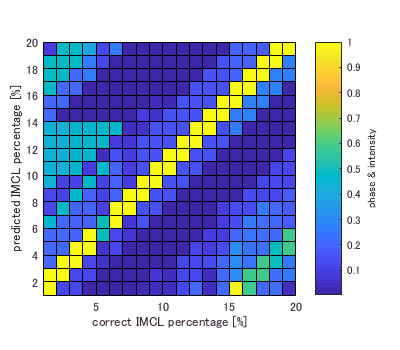

load("H:\result\2018_11_07_IMCL_estimation_principle_verifiacation\2018_11_11_maxrfsignal_detect_boundary_2layers\result.mat")
figure;
pcolor(max_signal_normalized.*homogeneity_total_normalized);
c = colorbar;
c.Label.String = 'phase & intensity';
axis equal
axis tight
xlabel('correct IMCL percentage [%]');
ylabel('predicted IMCL percentage [%]');
axis equal
axis tight
exportfig('H:/result/2018_11_07_IMCL_estimation_principle_verifiacation/2018_11_13_phase&intensity_normalized_eng','png',[400,350]);

load("H:\result\2018_11_07_IMCL_estimation_principle_verifiacation\2018_11_11_maxrfsignal_detect_boundary_2layers\result.mat")
figure;
pcolor(max_signal_normalized.*homogeneity_total_normalized);
c = colorbar;
c.Label.String = '位相・強度指標';
axis equal
axis tight
xlabel('正解IMCL占有率 [%]');
ylabel('予測IMCL占有率 [%]');
exportfig('H:/result/2018_11_07_IMCL_estimation_principle_verifiacation/2018_11_13_phase&intensity_normalized','png',[400,350]);

同じ媒質に対する推定IMCL率の変化に伴うhomogeneity_totalとmax_signalのプロファイ ル表示

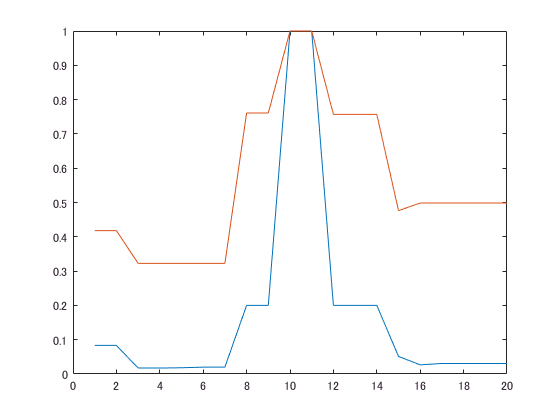

load("H:\result\2018_11_07_IMCL_estimation_principle_verifiacation\2018_11_11_maxrfsignal_detect_boundary_2layers\result.mat")
figure;
plot(homogeneity_total(:,10)/max(homogeneity_total(:,10)));
hold on
plot(max_signal(:,10)/max(max_signal(:,10)));figure;

homogeneity_total(~isfinite(homogeneity_total(:,1)),1) = 0;
plot(homogeneity_total(:,1)/max(homogeneity_total(:,1)));
hold on
max_signal(:,1)

ans =     1.6966
    1.6966
    1.4181
    1.4181
    1.4181
    0.7656
    0.7596
    0.7596
    0.7297
    0.7297


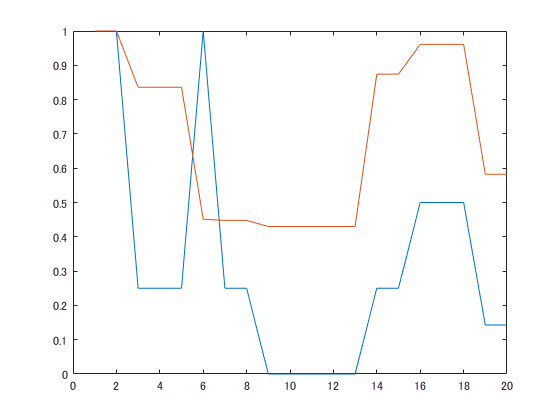

plot(max_signal(:,1)/max(max_signal(:,1)));

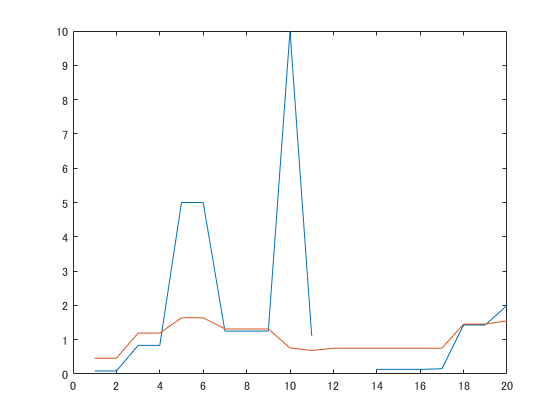

figure;
plot(homogeneity_total(:,5));
hold on
plot(max_signal(:,5));

信号の絶対値ではなく，圧力の最大値をとる点と整相加算での参照点との距離を評価指標にしたもの．これを，case26のIMAT構造においてIMCL占有率を1~20  %で変動させた媒質20個に対して上と同じように推定する

%%%%%%%%%%%%%%%%%%%%%%%%%%%%％％％％％％％%%%%%
% 対象：case26
% 焦点水平位置固定：y=0
% 境界面を検出→参照点の妥当性評価
% ch 50直下のピクセルにフォーカスをかける．
% 参照点：整相加算における参照点
% 比較する点：各chでのrf信号最大値(絶対値はとらない)
%誤検出が見られるが，反射強度を考慮して誤検出と判別できるようにする．
% フォーカス深度を１グリッドずつ変化させて，開口合成受信データを生成する．
% F値を固定する．最近接距離をいくつに設定する？
% x-axis: 20 mmのときに全素子を使うという前提を設ける．
% 対象にする媒質データ：case26を用いる．
% IMCL割合を0 %に固定する．
% kgrid.x_vec が0となるのは251番目の要素．
% グリッド幅が0.1 mm
% 素子間ピッチが0.4 mm
% よって，最近接深度(最近接距離は0.4 mm)
% 深度ごとの細かい素子割当は，floor()を用いる．
% 整相加算の際に参照する音速を1580 m/sとする．
% 整相加算の前に参照点と受信chごとの振幅(ヒルベルト変換後絶対値)最大値との距離の
% 合計を評価関数として媒質の均質性を評価することも同時に行う．
% update:rf-dataの配列サイズが大きくなってきたので，変数区分を細分化して各変数の呼び出し速度を上げる．[2018/11/05]
% update:for文ごとにフォルダを作成するようにする．フォルダごとにrfデータを保存する．
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

clear;
load("H:/data/kwave/config/t_pos_2board.mat");
pathname = sprintf('H:/data/kwave/result/2018_11_11_case26_variousIMCL/case26_IMCL%0.1f',1.0);
cd(pathname);
load('rfdata.mat');
load('kgrid.mat');
% load("H:/data/kwave/result/2018_10_21_point_medium/point_mudium5MHz/rfdata.mat");
% load("H:/data/kwave/result/2018_10_21_point_medium/point_mudium5MHz/medium.mat");
% load("H:/data/kwave/result/2018_10_21_point_medium/point_mudium5MHz/kgrid.mat");

% 初期設定
v_fat = 1450;%[m/s]
v_muscle = 1580;%[m/s]
rate_IMCL = linspace(1,20,20);
v_reference = zeros(1,length(rate_IMCL));
t_facing_distance = 0.04;%[m]
[~,num_receiver,num_transmitter] = size(rfdata);
num_echo_receiver = num_transmitter;
num_rate_IMCL = length(rate_IMCL);
num_medium  = num_rate_IMCL;
reference_point = zeros(1,num_echo_receiver);
reference_point_lowerlimit = zeros(1,num_echo_receiver);%均質性評価のためのRFデータマスキングに使う
reference_point_upperlimit = zeros(1,num_echo_receiver);%均質性評価のためのRFデータマスキングに使う
point_max_in_mask = zeros(1,num_echo_receiver);%マスク処理後のRFデータで振幅最大のサンプル点情報
distance_from_focal_point_all = zeros(1,num_echo_receiver);

num_depth = (t_pos(2,1)-t_pos(2,101))/kgrid.dx - 3;%'3'とあるのは，最近接距離が0.4 mmであることを考慮している．
focal_depth = zeros(1,num_depth);
focal_point = zeros(2,num_depth);
for ii = 1:num_depth
    focal_depth(1,ii) = (ii+3)*kgrid.dx;
    focal_point(2,ii) = t_pos(2,1)-focal_depth(1,ii);
    focal_point(1,ii) = 0;
end

ind_max_signal = zeros(num_rate_IMCL,num_medium);
max_signal = zeros(num_rate_IMCL,num_medium);
homogeneity_percel = zeros(num_rate_IMCL,num_echo_receiver);
homogeneity_total = zeros(num_rate_IMCL,num_medium);
focal_signal_total = zeros(num_depth,num_rate_IMCL,num_medium);
for ll = 1:num_medium
    pathname = sprintf('H:/data/kwave/result/2018_11_11_case26_variousIMCL/case26_IMCL%0.1f',ll);
    cd(pathname);
    load('rfdata.mat');
    load('kgrid.mat');
    [num_sample,~,~] = size(rfdata);
    for kk = 1:num_rate_IMCL
        %% 反射強度プロファイルを求める．
        v_reference(1,kk) = v_muscle*(1-rate_IMCL(1,kk)/100) + v_fat*(rate_IMCL(1,kk)/100);
        for ii = 1:num_depth
            target_element = find((-focal_depth(1,ii)/2<=t_pos(1,1:100)&(t_pos(1,1:100)<=focal_depth(1,ii)/2)));
            %受信用の参照点算出
            for jj = 1:num_echo_receiver
                distance_from_focal_point_all(1,jj) = norm(t_pos(:,jj) - focal_point(:,ii));
                delay_time_all = round(((distance_from_focal_point_all - focal_depth(1,ii))/v_reference(1,kk))/kgrid.dt);%[sample]
                reference_point(1,jj) = round(delay_time_all(1,jj)+(2*focal_depth(1,ii)/v_reference(1,kk))/kgrid.dt+25-1);
            end
            %送信ビームフォーミング（共通）
            focused_rfdata = transmit_focus(rfdata,target_element,num_sample,delay_time_all,num_echo_receiver);
            %受信ビームフォーカシング
            focal_signal_total(ii,kk,ll) =  receive_focus(focused_rfdata,target_element,reference_point);
        end
        %% 反射強度が最大の焦点位置を探索．
        [max_tmp,ind_tmp] = findpeaks(focal_signal_total(:,kk,ll),'Npeaks',1,'SortStr','descend');
        ind_max_signal(kk,ll) = ind_tmp;
        max_signal(kk,ll) = max_tmp;
        ii = ind_tmp;
        %% 参照点と波面との誤差を評価．
        %         focused_rfdata = zeros(num_sample,num_echo_receiver);
        target_element = find((-focal_depth(1,ii)/2<=t_pos(1,1:100)&(t_pos(1,1:100)<=focal_depth(1,ii)/2)));
        %受信用の参照点算出
        for jj = 1:num_echo_receiver
            distance_from_focal_point_all(1,jj) = norm(t_pos(:,jj) - focal_point(:,ii));
            delay_time_all = round(((distance_from_focal_point_all - focal_depth(1,ii))/v_reference(1,kk))/kgrid.dt);%[sample]
            reference_point(1,jj) = round(delay_time_all(1,jj)+(2*focal_depth(1,ii)/v_reference(1,kk))/kgrid.dt+25-1);
            %25はfocal_amplitudeを最大にするオフセット．
            reference_point_lowerlimit(1,jj) ...
                = round(delay_time_all(1,jj)*(v_reference(1,kk)/v_muscle)+(2*focal_depth(1,ii)/v_muscle)/kgrid.dt+25-1-1);
            reference_point_upperlimit(1,jj) ...
                = round(delay_time_all(1,jj)*(v_reference(1,kk)/v_fat)+(2*focal_depth(1,ii)/v_fat)/kgrid.dt+25-1);
            %どんなに遅延しても早く到達してもこの範囲内に焦点位置からのエコーパルスが入っているであろう上限・下限
        end
        %送信ビームフォーミング（共通）
        focused_rfdata = transmit_focus(rfdata,target_element,num_sample,delay_time_all,num_echo_receiver);
        focused_rfdata_masked = focused_rfdata;
        %RFデータマスキング（均質性評価のため）
        for jj = 1:num_echo_receiver
            focused_rfdata_masked(1:reference_point_lowerlimit(1,jj),jj) = 0;
            focused_rfdata_masked(reference_point_upperlimit(1,jj):end,jj) = 0;
        end
        [~,point_max_in_mask] = max(focused_rfdata_masked,[],1);
        for jj = 1:length(target_element)
            %均質性評価指標
            homogeneity_percel(kk,jj) = abs(point_max_in_mask(1,target_element(jj)) - reference_point(1,target_element(jj)));
        end
        homogeneity_total(kk,ll) = 1/(sum(homogeneity_percel(kk,:))/length(target_element));
        dst_path = sprintf('H:/result/2018_11_07_IMCL_estimation_principle_verifiacation/2018_11_11_maxrfsignal_detect_boundary_case26/true%d_assumption%d',...
            rate_IMCL(1,ll),rate_IMCL(1,kk));
        if ~exist(dst_path, 'dir')
            mkdir(dst_path);
        end
        save([dst_path,'\rfdata.mat'],'focused_rfdata','focused_rfdata_masked','homogeneity_percel');
        figure;
        imagesc(focused_rfdata_masked);
        hold on
        scatter(min(target_element):max(target_element),reference_point(min(target_element):max(target_element)),'red');
        scatter(min(target_element):max(target_element),point_max_in_mask(min(target_element):max(target_element)),'blue','filled');
        hold off
        xlabel('receiver[ch]');
        ylabel('time[sample]');
        axis square;
        axis tight;
        if ii<=30
            xlim([40 60])
        else
            xlim([min(target_element) max(target_element)])
        end
        ylim([reference_point_lowerlimit(50) reference_point_upperlimit(min(target_element))])
        colormap(bone);
        colorbar;
        caxis([min(min(focused_rfdata_masked)) max(max(focused_rfdata_masked))])
        savefig([dst_path,'\rfdata_masked.fig'])
        exportfig([dst_path,'\rfdata_masked'],'png',[400,400])
        close gcf
         figure;
        imagesc(focused_rfdata);
        hold on
        scatter(min(target_element):max(target_element),reference_point(min(target_element):max(target_element)),2,'red');
        scatter(min(target_element):max(target_element),point_max_in_mask(min(target_element):max(target_element)),2,'blue','filled');
        hold off
        xlabel('receiver[ch]');
        ylabel('time[sample]');
        axis square;
        axis tight;
        colormap(bone);
        colorbar;
        caxis([min(min(focused_rfdata_masked)) max(max(focused_rfdata_masked))])
        savefig([dst_path,'\rfdata_whole.fig'])
        exportfig([dst_path,'\rfdata_whole'],'png',[400,400])
        close gcf
    end
end
dst_path = sprintf('H:/result/2018_11_07_IMCL_estimation_principle_verifiacation/2018_11_11_maxrfsignal_detect_boundary_case26/');
save([dst_path,'\result.mat'],'ind_tmp','ind_max_signal','focal_depth','homogeneity_total','homogeneity_percel',...
    'reference_point','focused_rfdata','focused_rfdata_masked','focal_signal_total','max_signal');

dstpath = 'H:\result\2018_11_07_IMCL_estimation_principle_verifiacation\2018_11_11_maxrfsignal_detect_boundary_case26\'

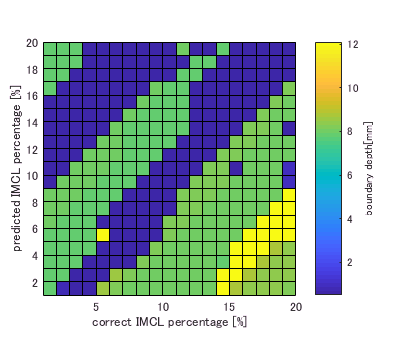

figure;
tmp = zeros(20,20);
for ii = 1:20
    tmp(ii,:) = focal_depth(1,ind_max_signal(ii,:))*1e3;
end
pcolor(tmp);
c = colorbar;
c.Label.String = 'boundary depth[mm]';
axis equal
axis tight
xlabel('correct IMCL percentage [%]');
ylabel('predicted IMCL percentage [%]');
axis equal
axis tight
exportfig([dstpath,'\2018_11_11_detection_depth_with_errors_boundary_position_detection_with_rfsignal_predeiction_vs_correct_IMCL_percentage_pcolor_without_abs_eng'],'png',[400,350]);

load("H:\result\2018_11_07_IMCL_estimation_principle_verifiacation\2018_11_11_maxrfsignal_detect_boundary_case26\result.mat");
dstpath = 'H:\result\2018_11_07_IMCL_estimation_principle_verifiacation\2018_11_11_maxrfsignal_detect_boundary_case26\'

dstpath = 'H:\result\2018_11_07_IMCL_estimation_principle_verifiacation\2018_11_11_maxrfsignal_detect_boundary_case26\'

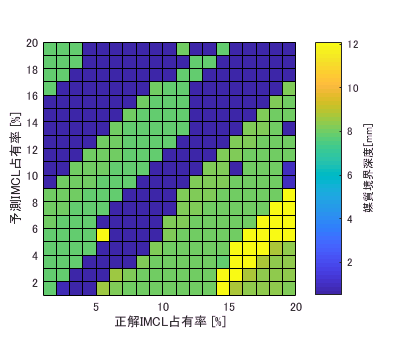

figure;
tmp = zeros(20,20);
for ii = 1:20
    tmp(ii,:) = focal_depth(1,ind_max_signal(ii,:))*1e3;
end
pcolor(tmp);
c = colorbar;
c.Label.String = '媒質境界深度[mm]';
axis equal
axis tight
xlabel('正解IMCL占有率 [%]');
ylabel('予測IMCL占有率 [%]');
axis equal
axis tight
exportfig([dstpath,'\2018_11_11_detection_depth_with_errors_boundary_position_detection_with_rfsignal_predeiction_vs_correct_IMCL_percentage_pcolor_without_abs'],'png',[400,350]);

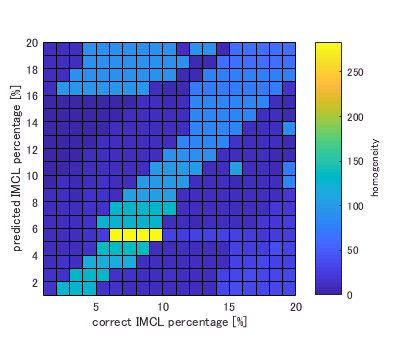

load("H:\result\2018_11_07_IMCL_estimation_principle_verifiacation\2018_11_11_maxrfsignal_detect_boundary_case26\result.mat");
dstpath = 'H:\result\2018_11_07_IMCL_estimation_principle_verifiacation\2018_11_11_maxrfsignal_detect_boundary_case26\';
homogeneity = 1./homogeneity_total;
figure;
pcolor(homogeneity);
colorbar;
c = colorbar;
c.Label.String = 'homogeneity';
axis equal
axis tight
xlabel('correct IMCL percentage [%]');
ylabel('predicted IMCL percentage [%]')
exportfig([dstpath,'\2018_11_11_boundary_position_detection_with_errors_boundary_position_detection_with_rfsignal_predeiction_vs_correct_IMCL_percentage_pcolor_without_abs_eng'],'png',[400,350]);

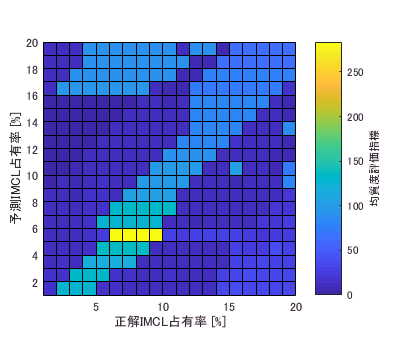

load("H:\result\2018_11_07_IMCL_estimation_principle_verifiacation\2018_11_11_maxrfsignal_detect_boundary_case26\result.mat");
dstpath = 'H:\result\2018_11_07_IMCL_estimation_principle_verifiacation\2018_11_11_maxrfsignal_detect_boundary_case26\';
homogeneity = 1./homogeneity_total;
figure;
pcolor(homogeneity);
c = colorbar;
c.Label.String = '均質度評価指標';
axis equal
axis tight
xlabel('正解IMCL占有率 [%]');
ylabel('予測IMCL占有率 [%]');
exportfig([dstpath,'\2018_11_11_boundary_position_detection_with_errors_boundary_position_detection_with_rfsignal_predeiction_vs_correct_IMCL_percentage_pcolor_without_abs'],'png',[400,350]);

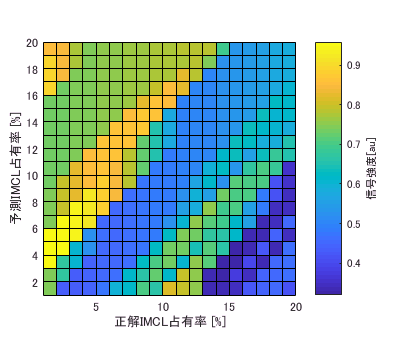

load("H:\result\2018_11_07_IMCL_estimation_principle_verifiacation\2018_11_11_maxrfsignal_detect_boundary_case26\result.mat");
dstpath = 'H:\result\2018_11_07_IMCL_estimation_principle_verifiacation\2018_11_11_maxrfsignal_detect_boundary_case26\';
figure;
pcolor(max_signal);
c = colorbar;
c.Label.String = '信号強度[au]';
axis equal
axis tight
xlabel('正解IMCL占有率 [%]');
ylabel('予測IMCL占有率 [%]');
axis equal
axis tight
exportfig([dstpath,'2018_11_11_max_intensity_with_errors_boundary_position_detection_with_rfsignal_predeiction_vs_correct_IMCL_percentage_pcolor_without_abs'],'png',[400,350]);

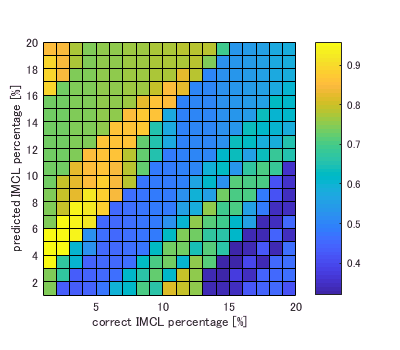

load("H:\result\2018_11_07_IMCL_estimation_principle_verifiacation\2018_11_11_maxrfsignal_detect_boundary_case26\result.mat");
dstpath = 'H:\result\2018_11_07_IMCL_estimation_principle_verifiacation\2018_11_11_maxrfsignal_detect_boundary_case26\';
figure;
pcolor(max_signal);
c = colorbar;
c.Label.String = 'Intensity[au]';
axis equal
axis tight
xlabel('correct IMCL percentage [%]');
ylabel('predicted IMCL percentage [%]');
exportfig([dstpath,'2018_11_11_max_intensity_with_errors_boundary_position_detection_with_rfsignal_predeiction_vs_correct_IMCL_percentage_pcolor_without_abs_eng'],'png',[400,350]);c = colorbar;

媒質のIMCL率が適切でなかった．修正をかける．

関数

function [focused_rfdata] = transmit_focus(rfdata,target_element,num_sample,delay_time_all,num_echo_receiver)
focused_rfdata = zeros(num_sample,num_echo_receiver);
for jj = 1:length(target_element)
    % 遅延処理
    delay_time = delay_time_all(1,target_element(jj));%[sample]
    read_range_rfdata = length(delay_time+1:num_sample);
    focused_rfdata(1:read_range_rfdata,:) = focused_rfdata(1:read_range_rfdata,:)...
        +  rfdata(delay_time+1:num_sample,1:100,target_element(jj));%整相加算
end
end

function [focal_signal_total] = receive_focus(focused_rfdata,target_element,reference_point)
focal_signal_total = 0;
for jj = 1:length(target_element)
    %受信ビームフォーミング（整相加算のため）
    focal_signal_total = focal_signal_total+ ...
        focused_rfdata(reference_point(1,target_element(1,jj)),target_element(1,jj))/length(target_element);
end
end